# Train Reinforcement Learning Agent in Basic Grid World

This example shows how to solve a grid world environment using reinforcement learning by training Q-learning and SARSA agents. For more information on these agents, see [Q-Learning Agents](docid:rl_ug#mw_0264db4d-9787-425a-8f8a-1426e5639719) and [SARSA Agents](docid:rl_ug#mw_b47b5155-a09e-4adf-81ed-7a5795fd2bd2).

To create a proper Grid World please see createGridWorld

This grid world environment has the following configuration and rules:

- The grid world is 5-by-5 and bounded by borders, with four possible actions (North = 1, South = 2, East = 3, West = 4).

- The agent begins from cell [2,1] (second row, first column).

- The agent receives a reward +10 if it reaches the terminal state at cell [5,5] (blue).

- The environment contains a special jump from cell [2,4] to cell [4,4] with a reward of +5.

- The agent is blocked by obstacles (black cells).

- All other actions result in –1 reward.

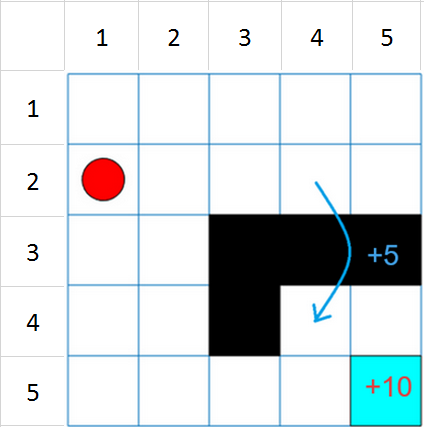

## Create Grid World Environment

Create the basic grid world environment.

env = rlPredefinedEnv("BasicGridWorld");

To specify that the initial state of the agent is always [2,1], create a reset function that returns the state number for the initial agent state. This function is called at the start of each training episode and simulation. States are numbered starting at position [1,1]. The state number increases as you move down the first column and then down each subsequent column. Therefore, create an anonymous function handle that sets the initial state to `2`.

env.ResetFcn = @() 2;

Fix the random generator seed for reproducibility.

rng('default')
rng(0)

## Create Q-Learning Agent

To create a Q-learning agent, first create a Q table using the observation and action specifications from the grid world environment. Set the learning rate of the representation to 1.

qTable = rlTable(getObservationInfo(env),getActionInfo(env));
qRepresentation = rlQValueRepresentation(qTable,getObservationInfo(env),getActionInfo(env));
qRepresentation.Options.LearnRate = 1;

Next, create a Q-learning agent using this table representation and configure the epsilon-greedy exploration. For more information on creating Q-learning agents, see [`rlQAgent`](docid:rl_ref#mw_b6721f63-a5be-47ea-9325-78f7b379ae30) and [`rlQAgentOptions`](docid:rl_ref#mw_383e9fbf-e99d-4af3-b250-49c6c4ae6f3f).

agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .04;
qAgent = rlQAgent(qRepresentation,agentOpts);

## Train Q-Learning Agent

To train the agent, first specify the training options. For this example, use the following options:

- Train for at most 200 episodes. Specify that each episode lasts for most 50 time steps.

- Stop training when the agent receives an average cumulative reward greater than 10 over 30 consecutive episodes.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.MaxEpisodes= 200;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 11;
trainOpts.ScoreAveragingWindowLength = 30;

Train the Q-learning agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training can take several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

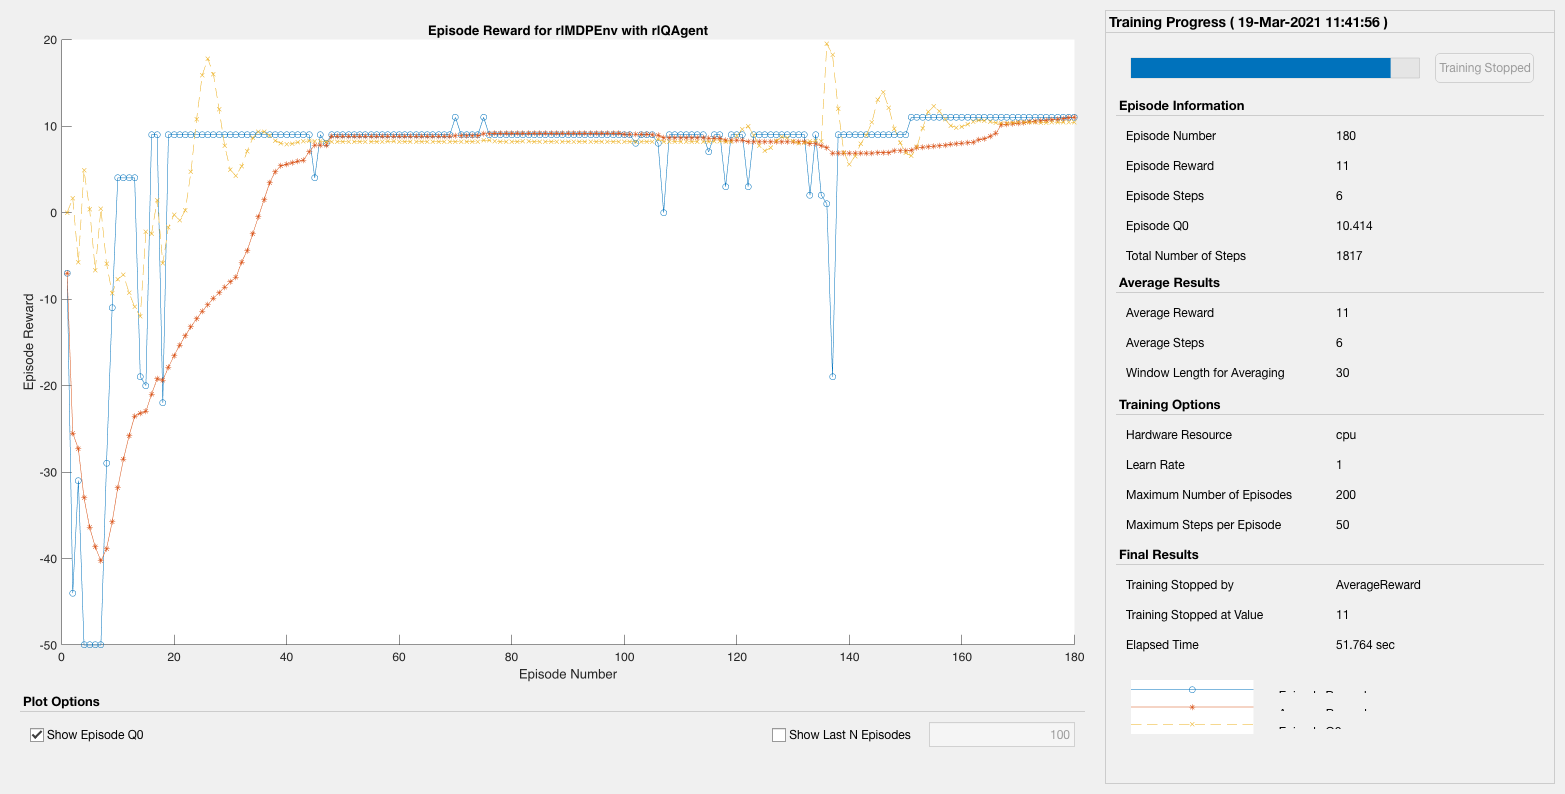

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(qAgent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('basicGWQAgent.mat','qAgent')
end

The **Episode Manager** window opens and displays the training progress.

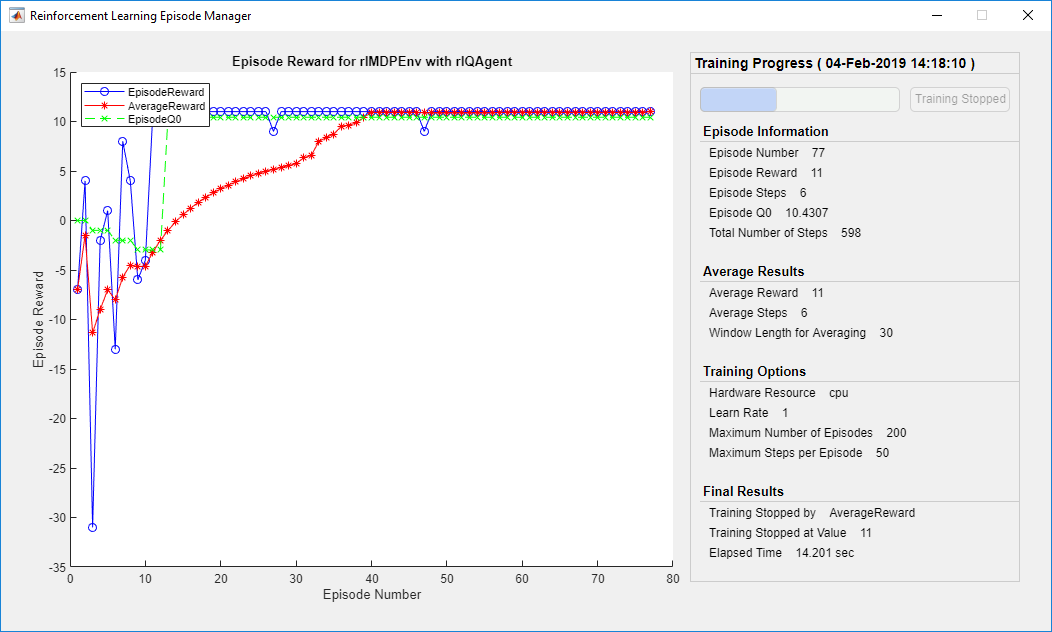

## Validate Q-Learning Results

To validate the training results, simulate the agent in the training environment.

Before running the simulation, visualize the environment and configure the visualization to maintain a trace of the agent states.

plot(env)
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;

Simulate the agent in the environment using the [sim](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf) function.

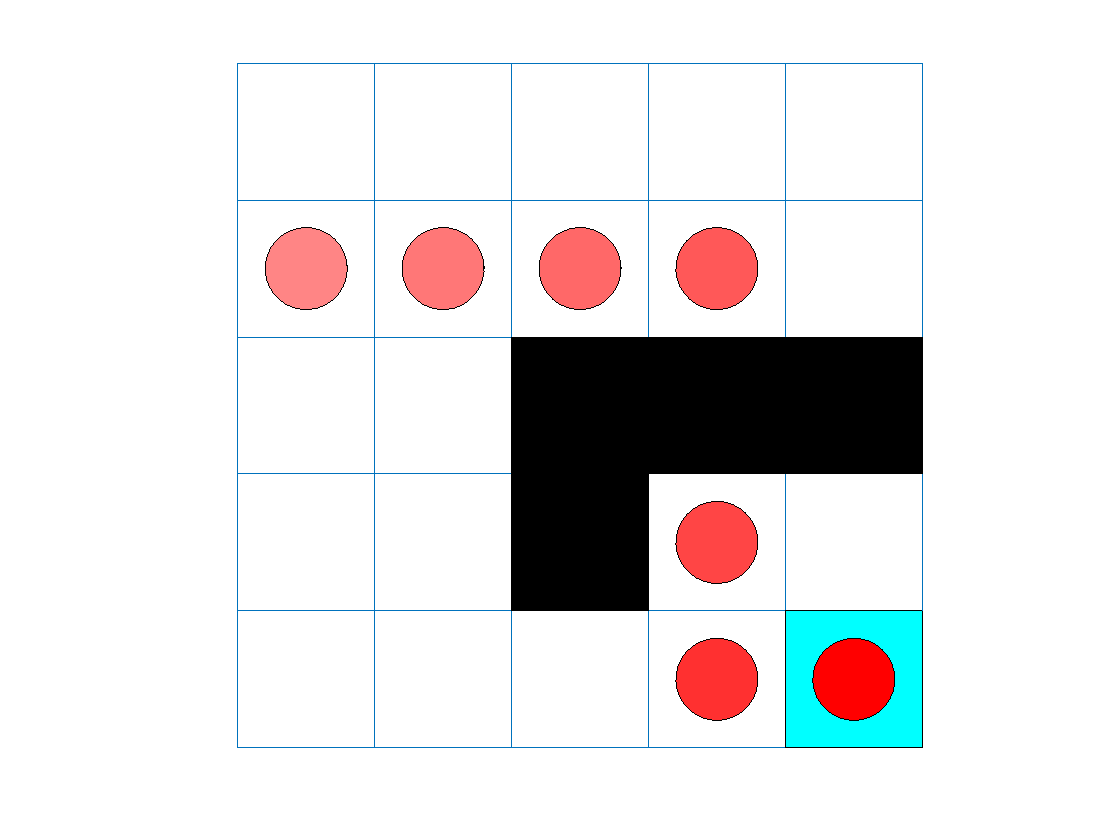

sim(qAgent,env)

The agent trace shows that the agent successfully finds the jump from cell [2,4] to cell [4,4].

## Create and Train SARSA Agent

To create a SARSA agent, use the same Q table representation and epsilon-greedy configuration as for the Q-learning agent. For more information on creating SARSA agents, see [`rlSARSAAgent`](docid:rl_ref#mw_714fff45-1dbf-4036-8111-baf8623cfc50) and [`rlSARSAAgentOptions`](docid:rl_ref#mw_e6f44861-bdb5-45f2-a8dc-c2adec71ec8d).

agentOpts = rlSARSAAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = 0.04;
sarsaAgent = rlSARSAAgent(qRepresentation,agentOpts);

Train the SARSA agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training can take several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;

if doTraining
    % Train the agent.
    trainingStats = train(sarsaAgent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('basicGWSarsaAgent.mat','sarsaAgent')
end

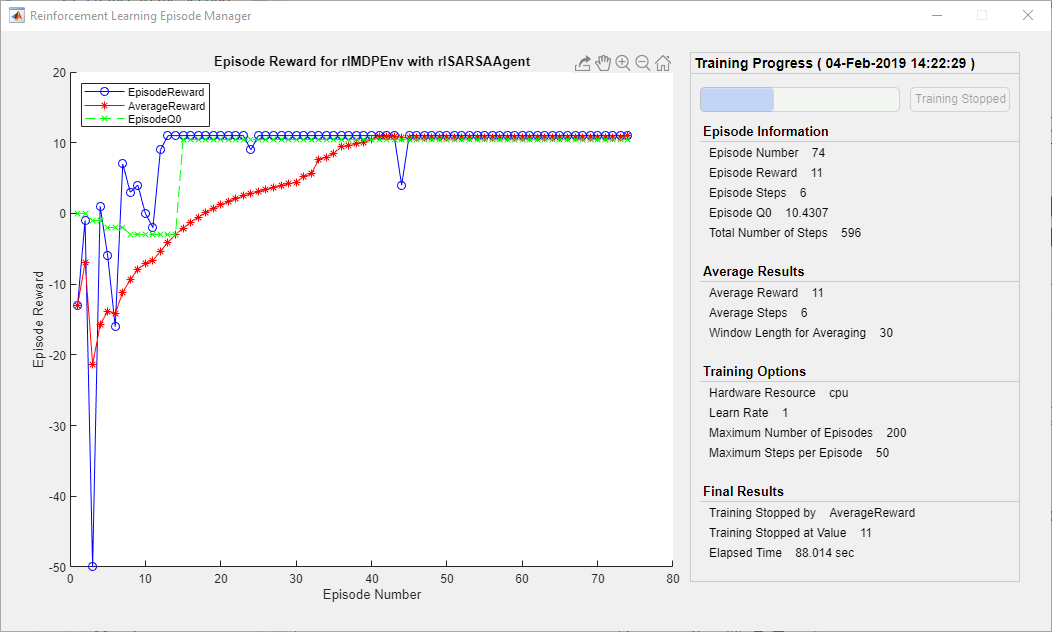

## Validate SARSA Training

To validate the training results, simulate the agent in the training environment.

plot(env)
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;

Simulate the agent in the environment.

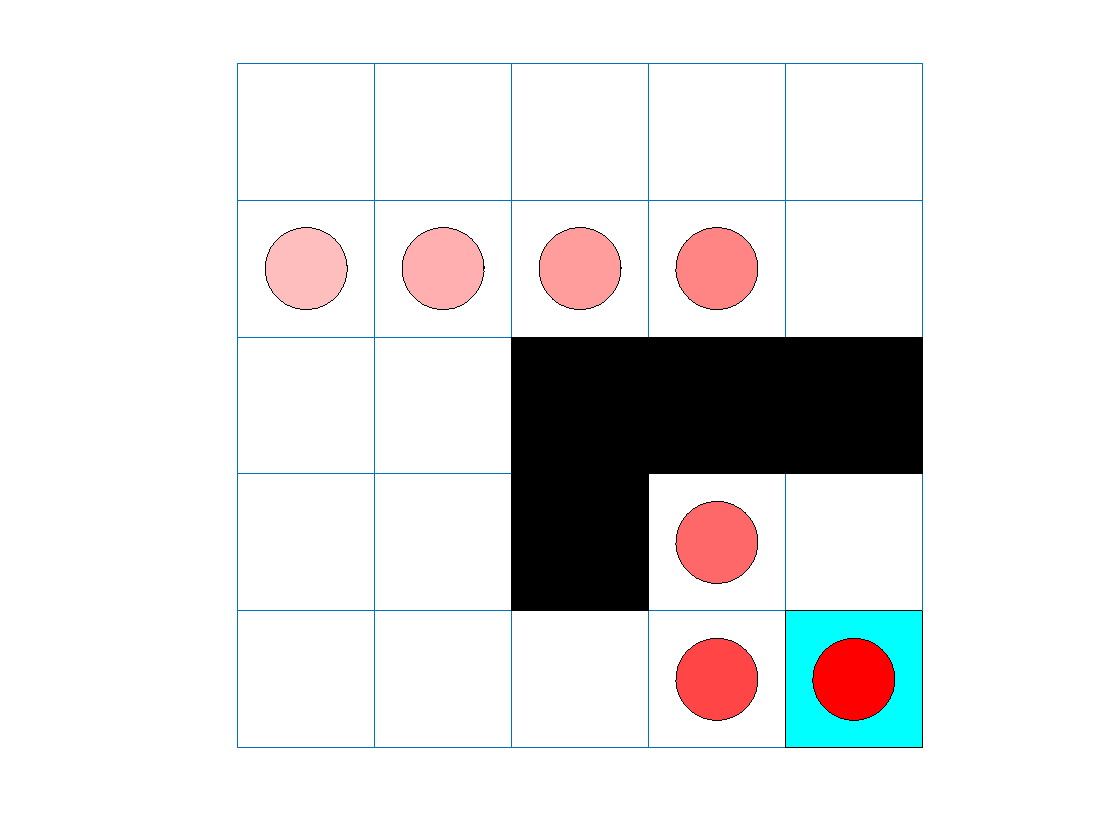

sim(sarsaAgent,env)

The SARSA agent finds the same grid world solution as the Q-learning agent.

*Copyright 2019 The MathWorks, Inc.*